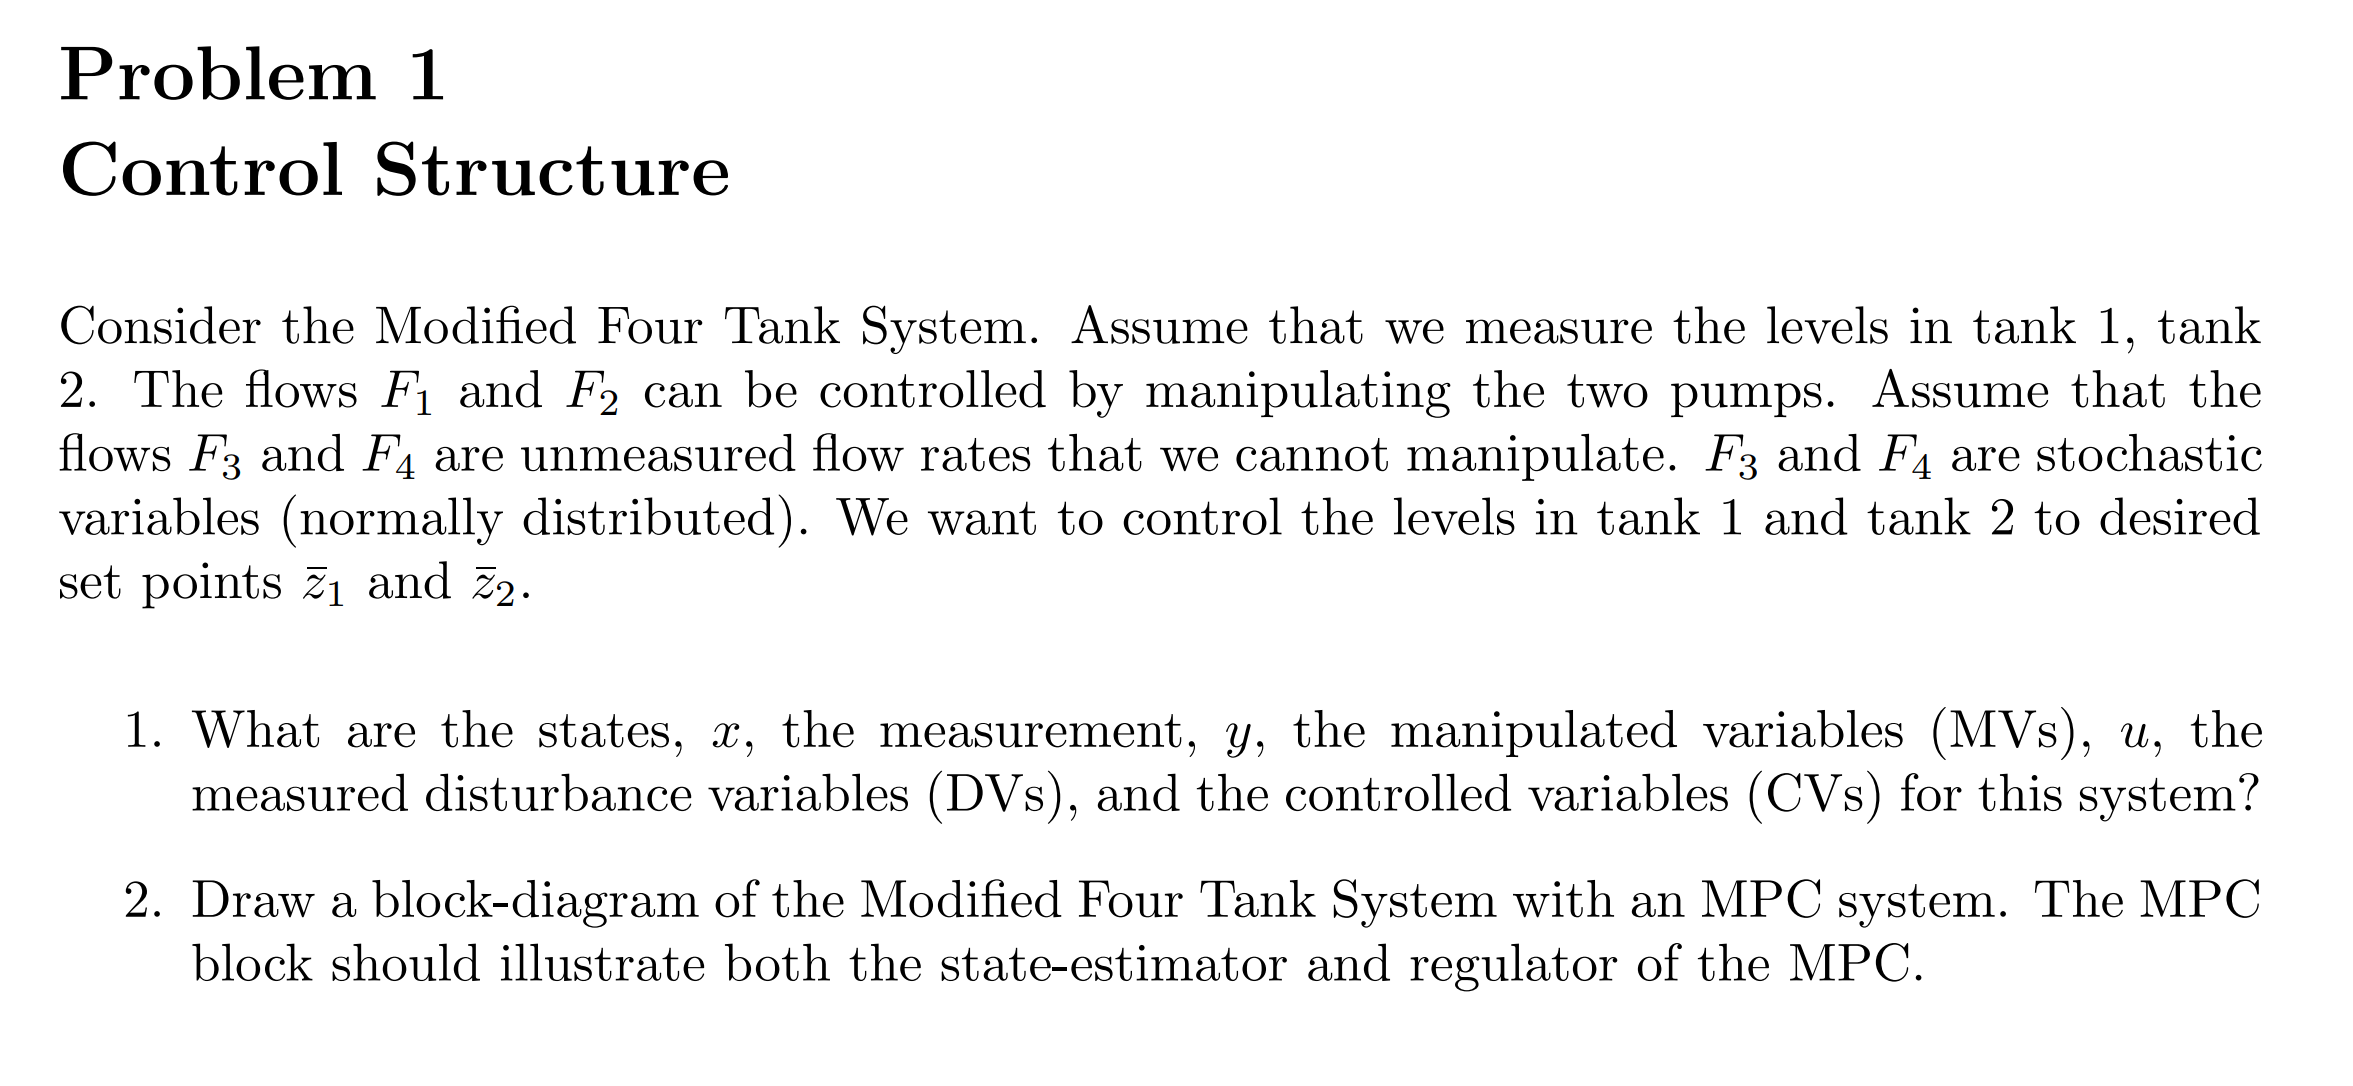

x: m1,m2,m3,m4

y:h1,h2,h3,h4

MVs,u:F1,F2

DVs,d:F3 F4

CVs,u:h1,h2

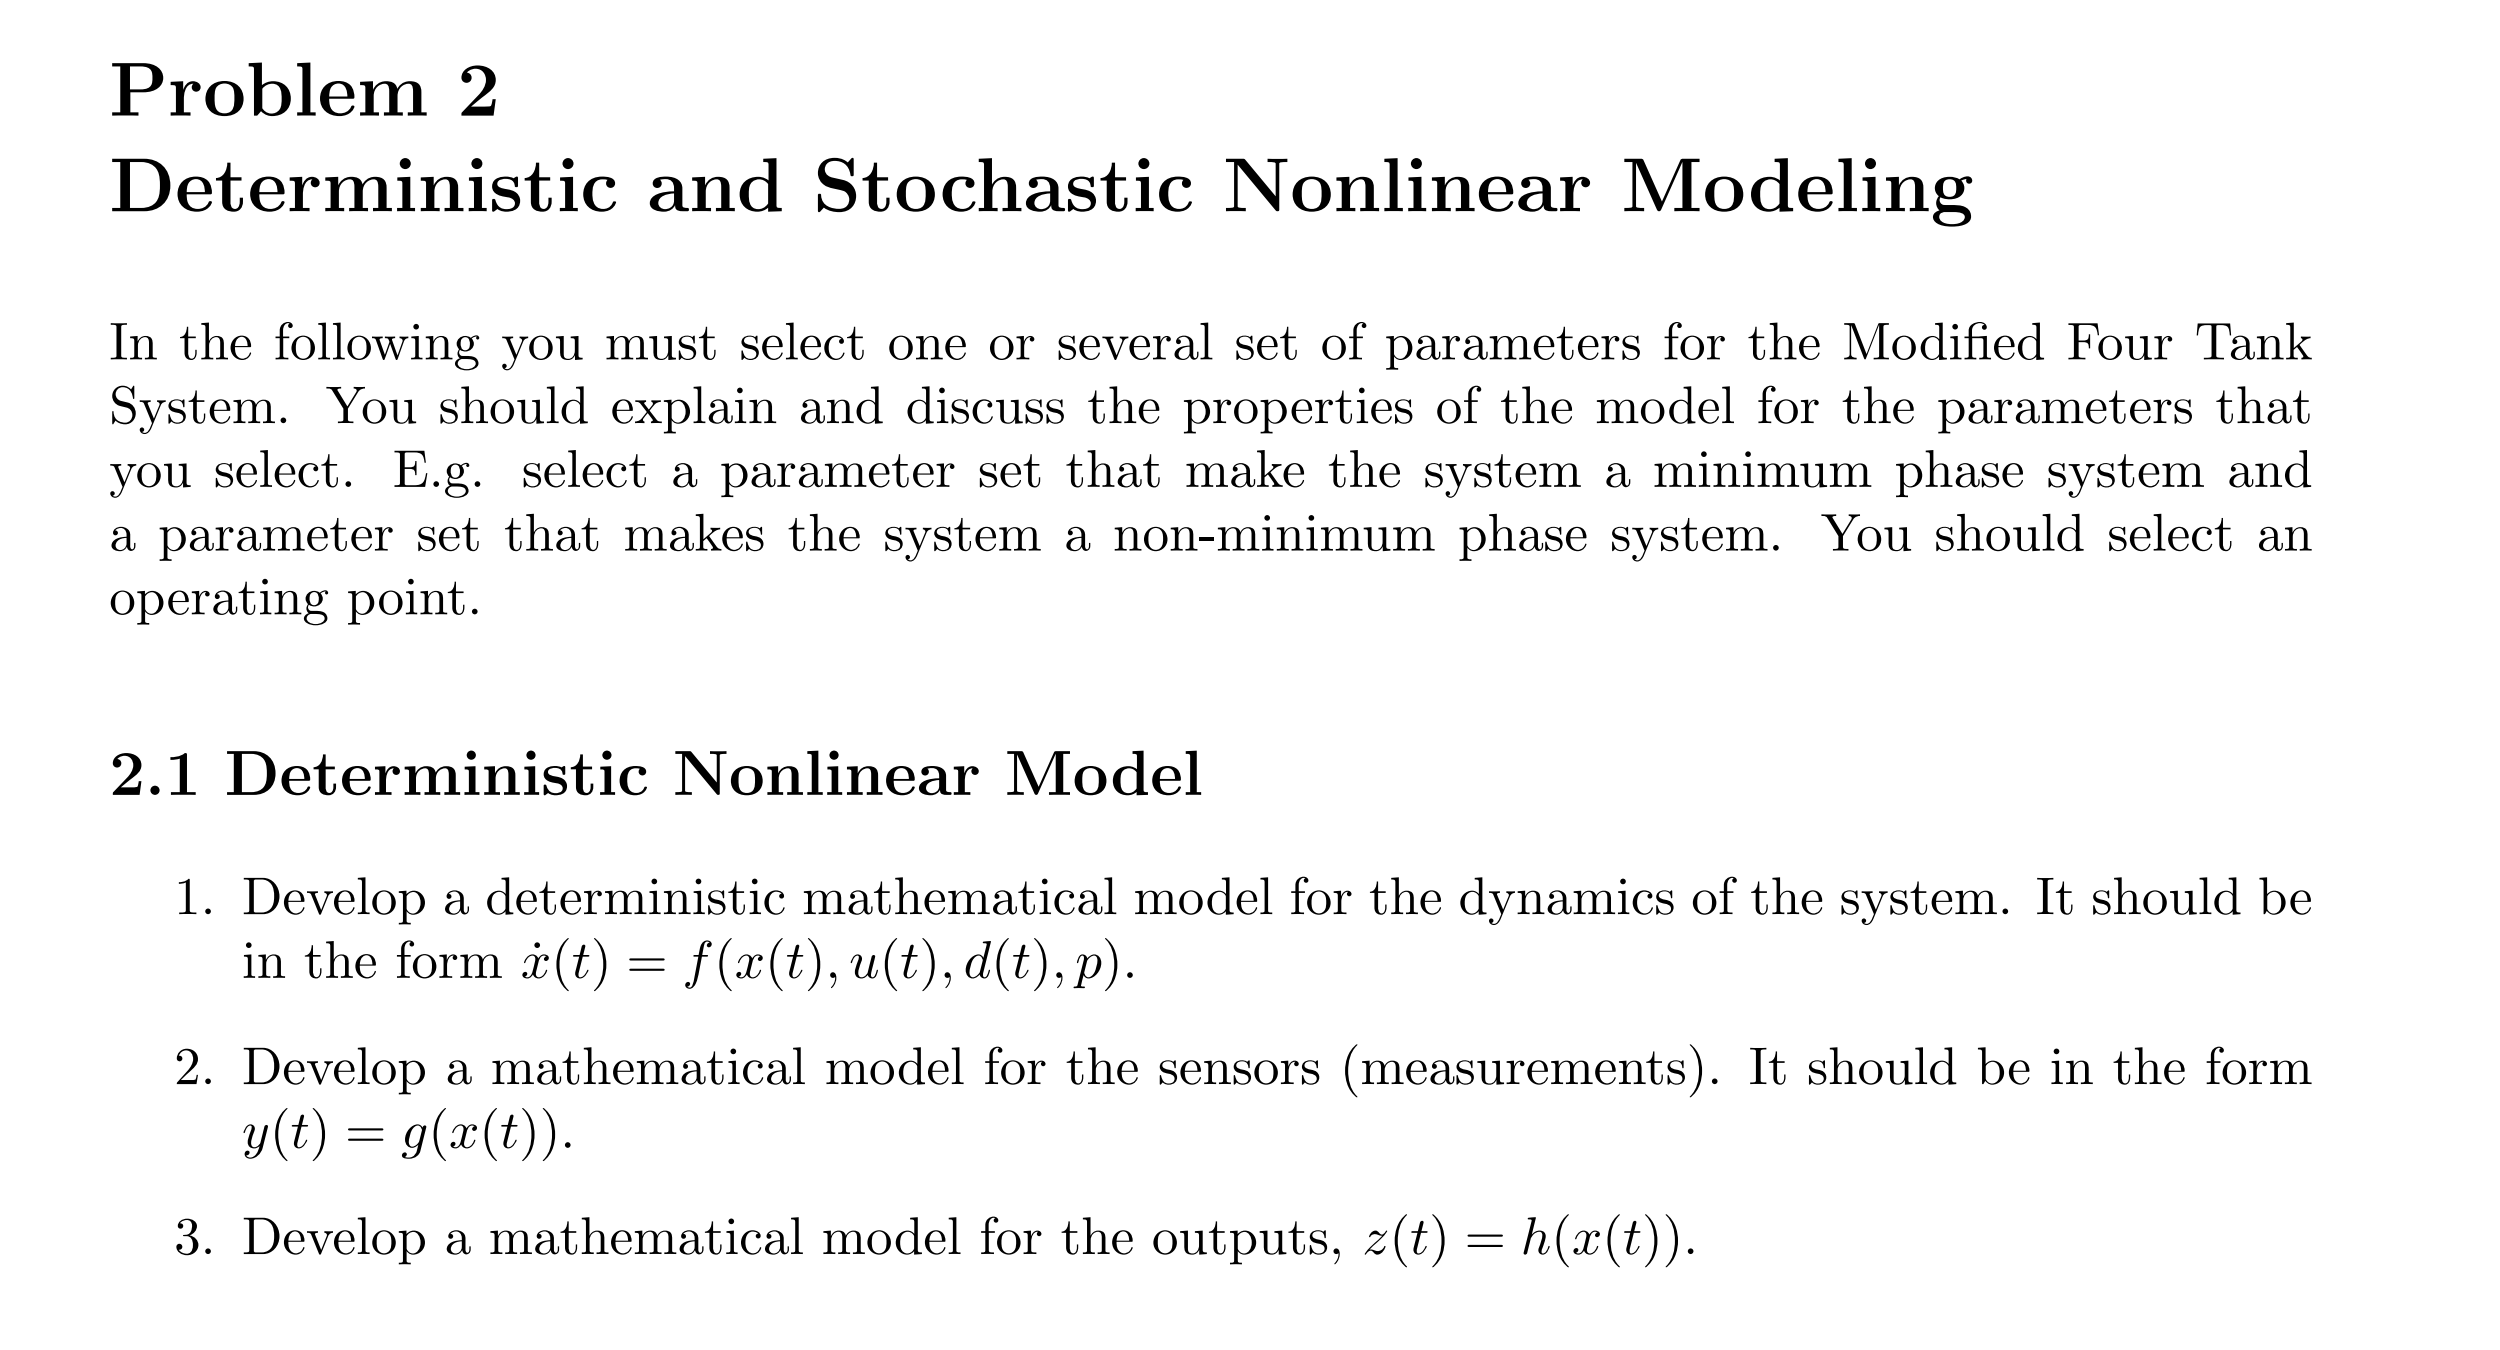

% --------------------------------------------------------------
% Parameters
% --------------------------------------------------------------
a1 = 1.2272 %[cm2] Area of outlet pipe 1
a2 = 1.2272 %[cm2] Area of outlet pipe 2
a3 = 1.2272 %[cm2] Area of outlet pipe 3 1.2272
a4 = 1.2272 %[cm2] Area of outlet pipe 4
A1 = 380.1327 %[cm2] Cross sectional area of tank 1
A2 = 380.1327 %[cm2] Cross sectional area of tank 2
A3 = 380.1327 %[cm2] Cross sectional area of tank 3 380
A4 = 380.1327 %[cm2] Cross sectional area of tank 4
gamma1 = 0.45; % Flow distribution constant. Valve 1 0.45
gamma2 = 0.40; % Flow distribution constant. Valve 2 0.40
g = 981; %[cm/s2] The acceleration of gravity
rho = 1.00; %[g/cm3] Density of water
p = [a1; a2; a3; a4; A1; A2; A3; A4; gamma1; gamma2; g; rho];
% --------------------------------------------------------------
%a3 a4:1.2272 Non-minimum phase system
%a3 a4:8 Minimum phase system

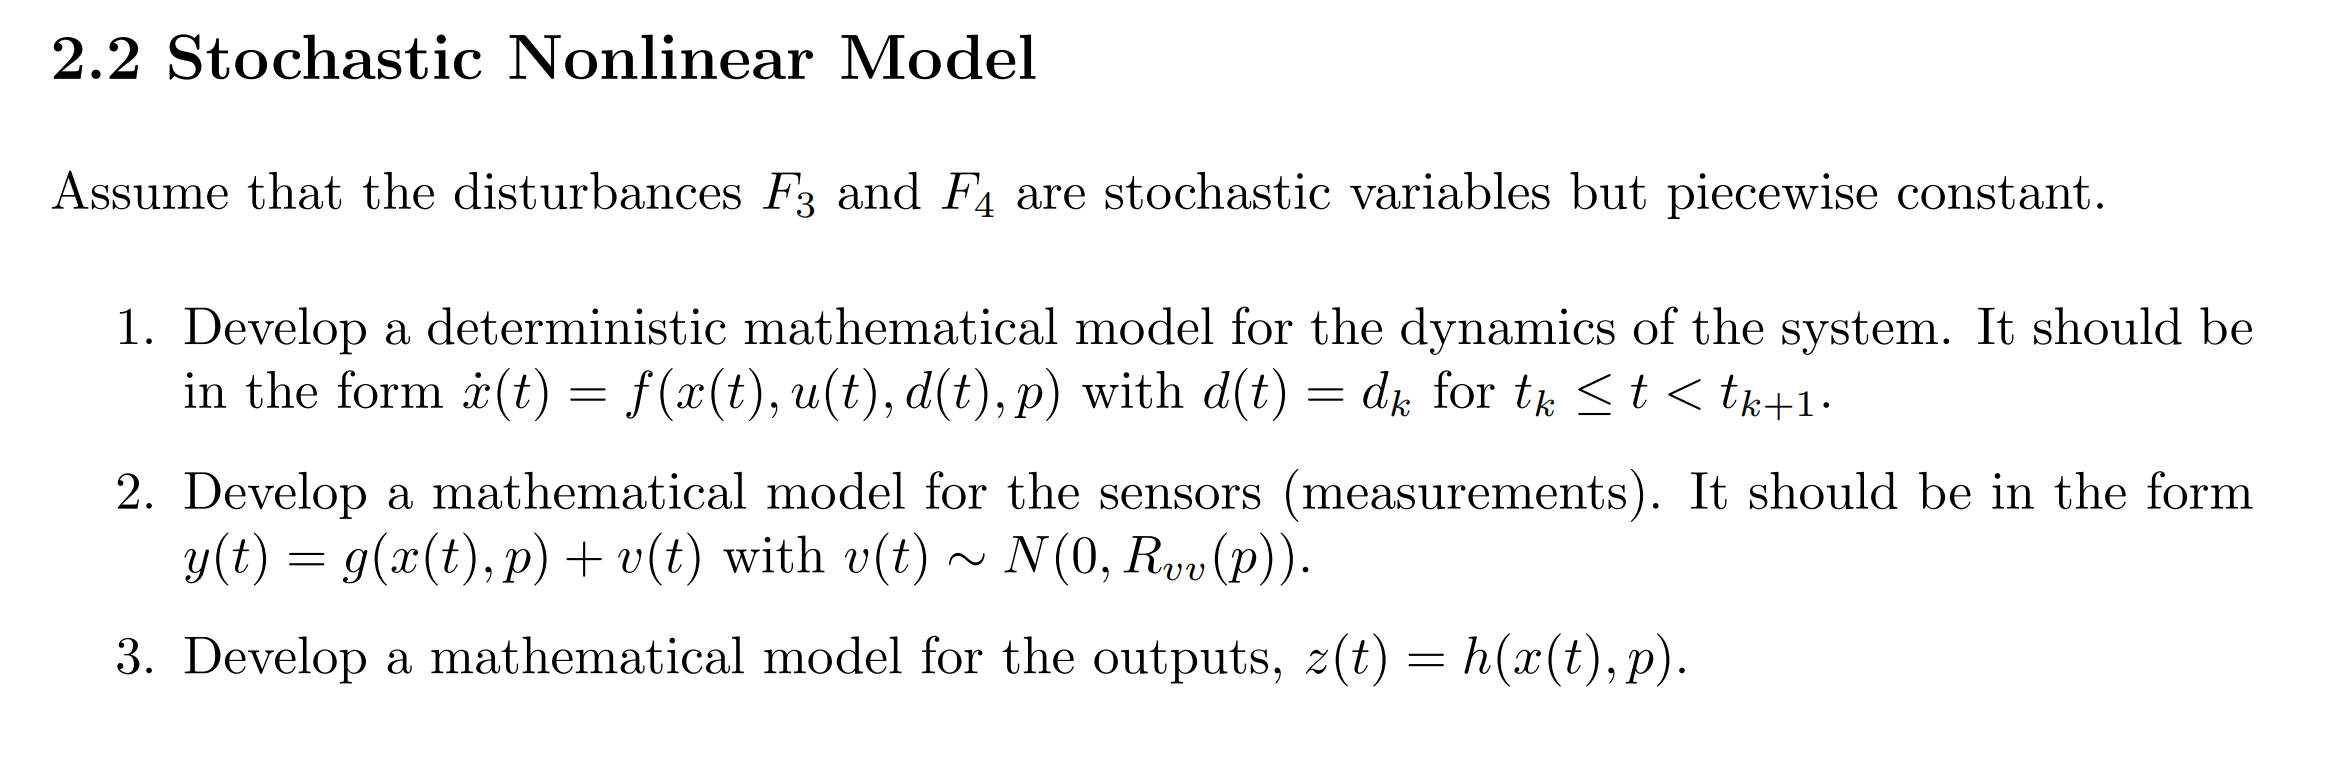

t0 = 0.0; % [s] Initial time
t_final = 20*60; % [s] Final time
Ts = 4; % [s] Sample Time
t = [t0:Ts:t_final]'; % [s] Sample instants
N = length(t);
m10 = 0; % [g] Liquid mass in tank 1 at time t0
m20 = 0; % [g] Liquid mass in tank 2 at time t0
m30 = 0; % [g] Liquid mass in tank 3 at time t0
m40 = 0; % [g] Liquid mass in tank 4 at time t0
F1 = 300; % [cm3/s] Flow rate from pump 1
F2 = 300; % [cm3/s] Flow rate from pump 2
x0 = [m10; m20; m30; m40];
u = [repmat(F1,1,N); repmat(F2,1,N)];
% Process Noise
Q = [20^2 0;0 40^2];
Lq = chol(Q,'lower');
w = Lq*randn(2,N);
% Measurement Noise
R = eye(4);
Lr = chol(R,'lower');
v = Lr*randn(4,N);
figure;
plot(v(1,:))
title('measurement noise')

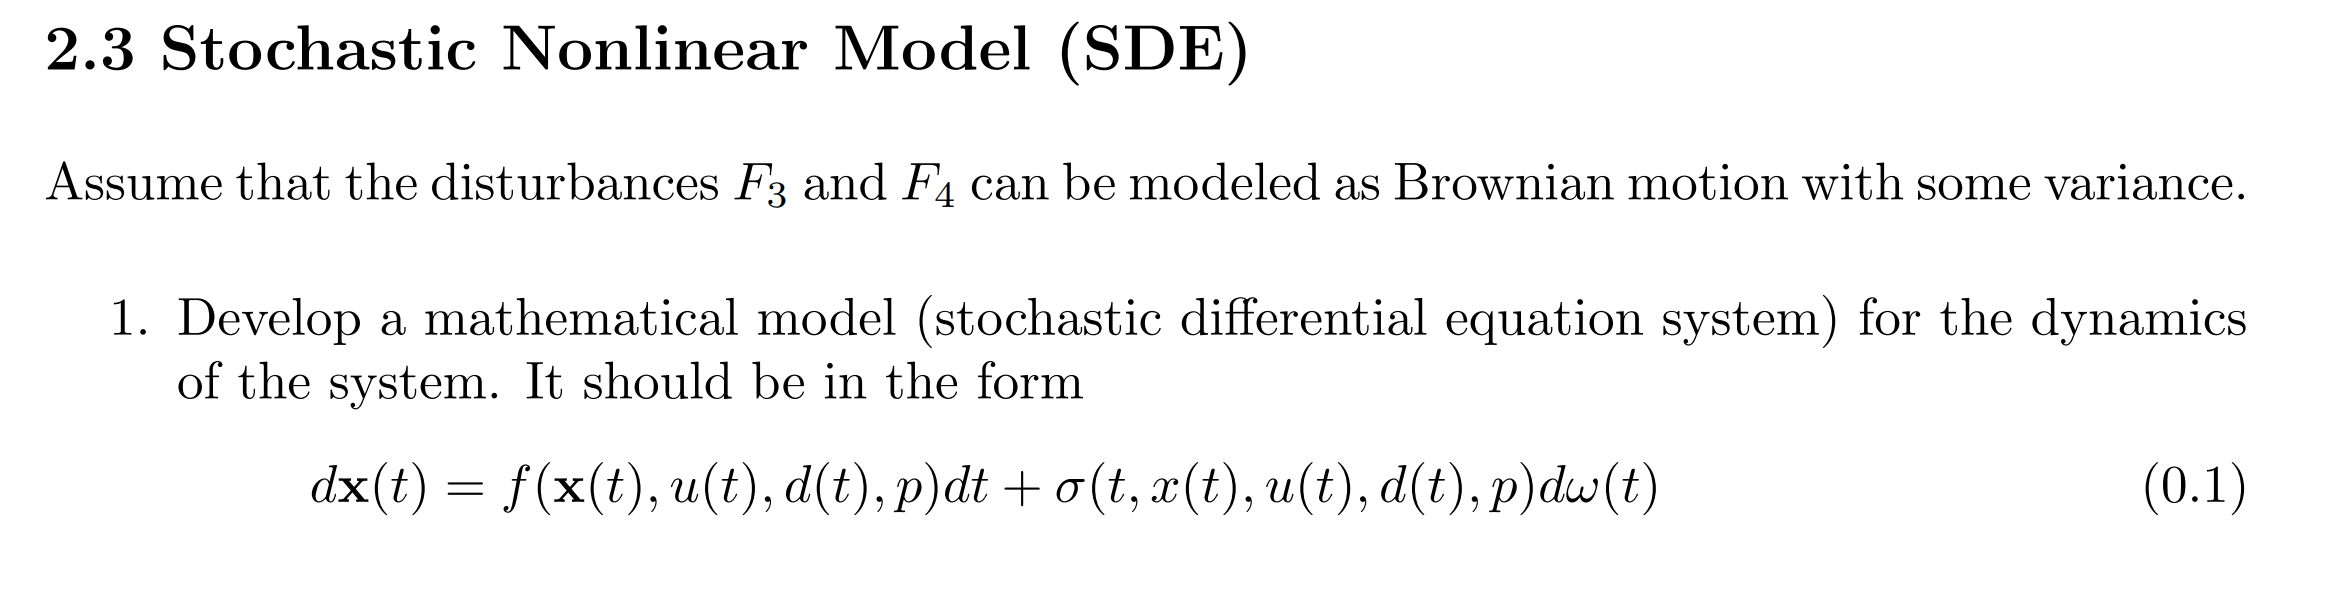

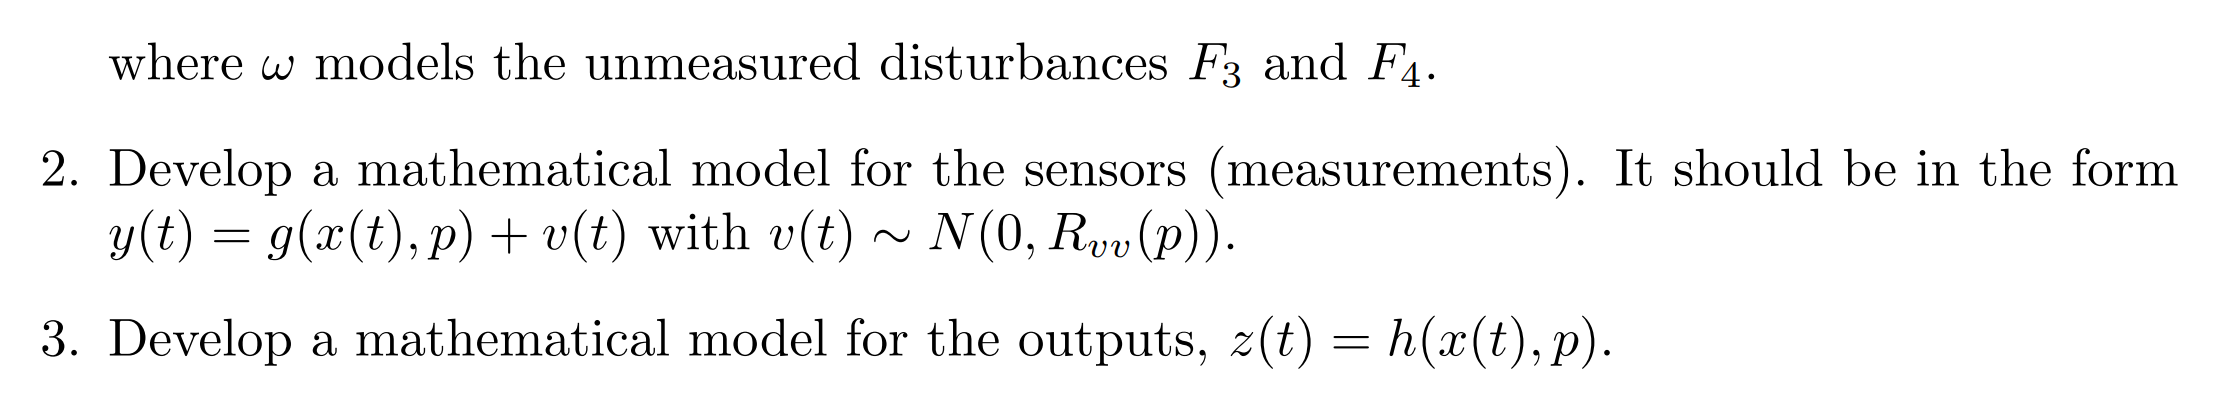

% Scalar Standard Brownian Motion = Standard Wiener Process
Ns = 2; % Number of realizations
Ts=4;
N = t_final/Ts; % Number of time steps
seed = 100; % Seed for reproducibility
[W,Tw,dW] = ScalarStdWienerProcess(t_final,N,Ns,seed);
plot(Tw,W,'linewidth',2)